cd(fileparts(matlab.desktop.editor.getActiveFilename))
close all; clearvars; clc

data = readtable("../../results/long-tables/rmse_raw_data.csv", "VariableNamingRule","preserve")

data = 810×6 table
    Participant ID    Neurological Condition          Decoder Type          Trial ID       Gesture Type          RMSE  
    ______________    ______________________    ________________________    ________    ___________________    ________

          1                {'Paretic'}          {'Co-Adaptive Learning'}       1        {'Co-Activation'  }     0.34794
          1                {'Paretic'}          {'Co-Adaptive Learning'}       1        {'Differentiation'}     0.11581
          1                {'Paretic'}          {'Co-Adaptive Learning'}       2        {'Co-Activation'  }     0.28142
          1                {'Paretic'}          {'Co-Adaptive Learning'}       2        {'Differentiation'}     0.22289
          1                {'Paretic'}          {'Co-Ada

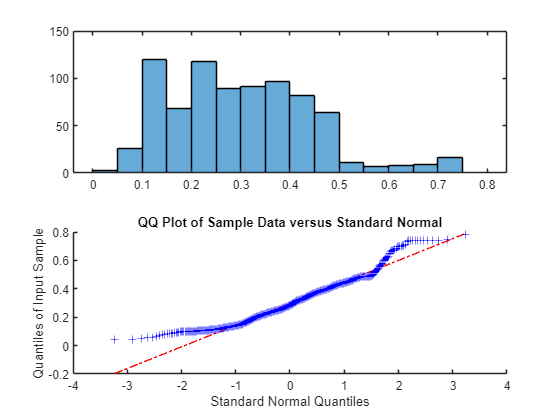

figure();
tlo = tiledlayout("flow");
nexttile; histogram(data.("RMSE"))
nexttile; qqplot(data.("RMSE"))

adtest(data.("RMSE"))

ans = logical
   1


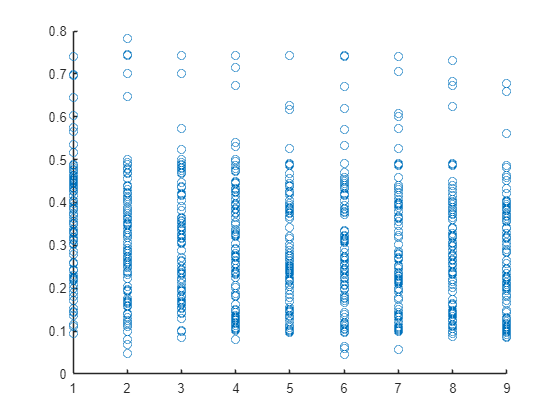

figure();
scatter(data.("Trial ID"), data.("RMSE"))

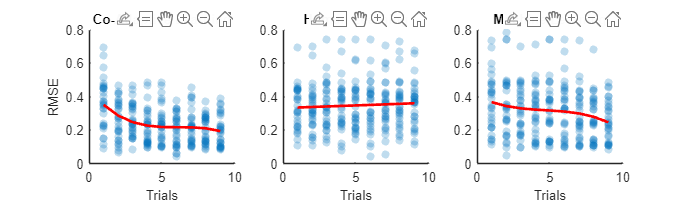

fig_h = figure();
set(fig_h, 'Renderer', 'painters');
set(fig_h, "Units","centimeters", "Position", [15, 5, 18.2, 11.25/2])%IEEE two-col golden
tlo = tiledlayout(1,3);
FIRST_FLAG = true;
for i = unique(data.("Decoder Type"))'
cond_idxs = ismember(data.("Decoder Type"), i);
plotting_data = data(cond_idxs, :);
ax = nexttile;
scatter(plotting_data.("Trial ID"),plotting_data.("RMSE"), "filled", MarkerFaceAlpha=0.25)
hold on
glm_model = fit(plotting_data.("Trial ID"), plotting_data.("RMSE"), 'poly3');
rmse_fit = feval(glm_model, unique(data.("Trial ID")));
plot(unique(data.("Trial ID")), rmse_fit, LineWidth=2, Color='red')
hold off
title(ax, i)
xlabel("Trials")
if FIRST_FLAG 
    FIRST_FLAG = false;
    ylabel("RMSE")
end
end
fontsize(fig_h, 10,"points")%PPT

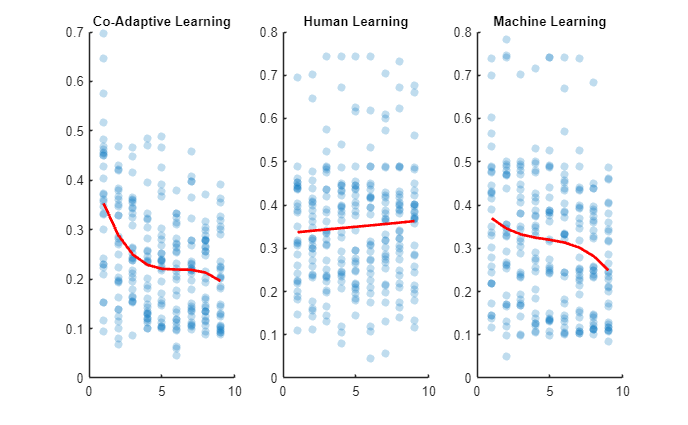

print(fig_h, '../../results/eps-figs/raw-rmse-dectype', '-depsc', '-r600', '-vector')

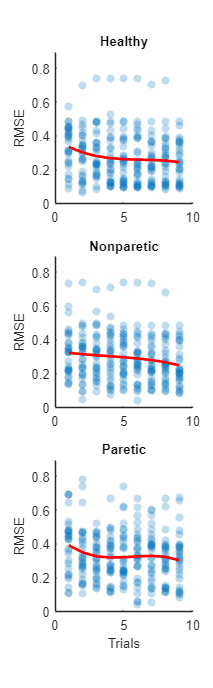

fig_h = figure();
set(fig_h, 'Renderer', 'painters');
set(fig_h, "Units","centimeters", "Position", [15, 5, 11.25/2, 18.2])%IEEE two col golden
tlo = tiledlayout(3,1);
for i = unique(data.("Neurological Condition"))'
cond_idxs = ismember(data.("Neurological Condition"), i);
plotting_data = data(cond_idxs, :);
ax = nexttile;
scatter(plotting_data.("Trial ID"),plotting_data.("RMSE"), "filled", MarkerFaceAlpha=0.25)
hold on
glm_model = fit(plotting_data.("Trial ID"), plotting_data.("RMSE"), 'poly3');
rmse_fit = feval(glm_model, unique(data.("Trial ID")));
plot(unique(data.("Trial ID")), rmse_fit, LineWidth=2, Color='red')
hold off
title(ax, i)
ylim([0 0.9])
ylabel("RMSE")
end
xlabel("Trials")
fontsize(fig_h, 10,"points")%PPT

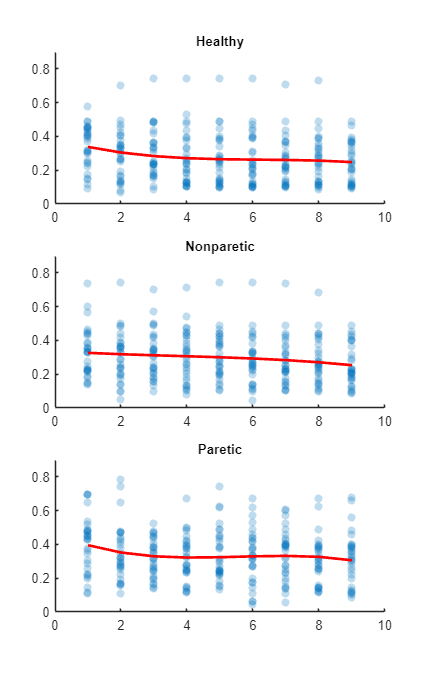

print(fig_h, '../../results/eps-figs/raw-rmse-neurocond', '-depsc', '-r600', '-vector')

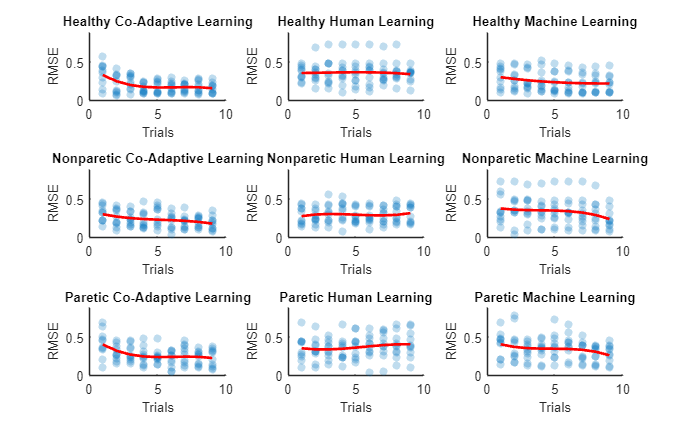

fig_h = figure();
set(fig_h, 'Renderer', 'painters');
set(fig_h, "Units","centimeters", "Position", [15, 5, 18.2, 11.25])%IEEE two col golden
tlo = tiledlayout(3,3);
for i = unique(data.("Neurological Condition"))'
cond_idxs = ismember(data.("Neurological Condition"), i);
plotting_data_lvl_1 = data(cond_idxs, :);
for j = unique(plotting_data_lvl_1.("Decoder Type"))'
cond_idxs = ismember(plotting_data_lvl_1.("Decoder Type"), j);
plotting_data = plotting_data_lvl_1(cond_idxs, :);
ax = nexttile;
scatter(plotting_data.("Trial ID"),plotting_data.("RMSE"), "filled", MarkerFaceAlpha=0.25)
hold on
glm_model = fit(plotting_data.("Trial ID"), plotting_data.("RMSE"), 'poly3');
rmse_fit = feval(glm_model, unique(data.("Trial ID")));
plot(unique(data.("Trial ID")), rmse_fit, LineWidth=2, Color='red')
hold off
ylim([0 0.9])
title(ax, i+" "+j)
end
end
fontsize(fig_h, 10,"points")%PPT

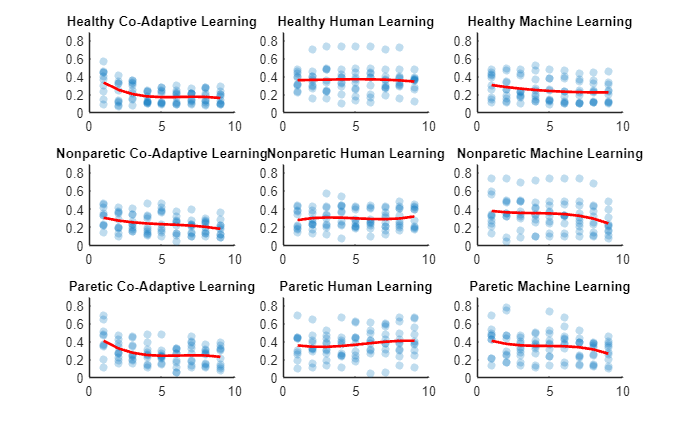

print(fig_h, '../../results/eps-figs/raw-rmse-2-factor', '-depsc', '-r600', '-vector')